clc; clear all; close all;

img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

RGB = imread(string(fullfile(img_path, T{1,1})));%Aquí elijes la imagen
Ig=rgb2gray(RGB);
Ig=double(Ig);
Ig=Ig.^4;

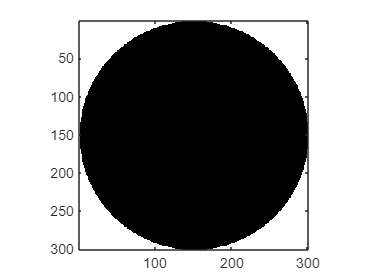

% Dimensiones de la matriz
n = 300;

% Crear una matriz de coordenadas
[x, y] = meshgrid(-n/2:n/2-1, -n/2:n/2-1);

% Calcular la distancia desde el centro
distancia = sqrt(x.^2 + y.^2);

% Crear el círculo: los puntos dentro del radio tendrán un valor de 1, el resto 0
radio = n/2;
circulo = distancia <= radio;

% Visualizar el círculo
imagesc(circulo);
colormap([1 1 1; 0 0 0]);
axis square;

Results=conv2(Ig,circulo);

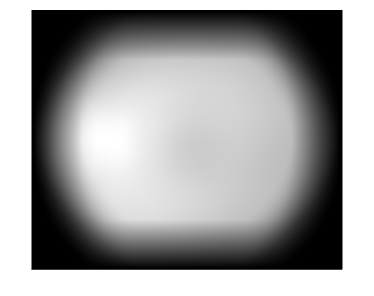

imshow(Results,[]);

%Encuentra el valor máximo y su índice lineal
[val_max, ind_lineal] = max(Results(:));

% Convierte el índice lineal a subíndices
[fila, columna] = ind2sub(size(Results), ind_lineal);

% Muestra las coordenadas del valor máximo
fprintf('El valor máximo es %d y se encuentra en la fila %d, columna %d.\n', val_max, fila, columna);

El valor máximo es 3.207711e+05 y se encuentra en la fila 1486, columna 816.


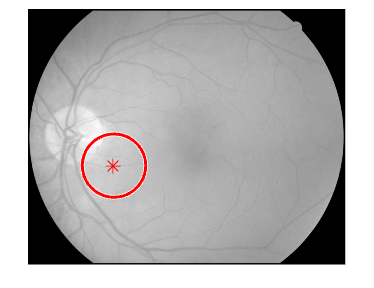

figure;
imshow(Ig,[]);
hold on
plot(columna, fila, 'r*', 'MarkerSize', 10);
viscircles([columna, fila],300);
hold off